# RLS Algorithm

clear; close all;

## Audio Init


[noiseReference, fs] = audioread("noisein.wav");
[numNoise, fs] = audioread("instrumentalnoisy.wav");
[numFiltered, fs] = audioread("instrumentalclean.wav");
ts = 1 / fs; % Sampling Period
k = 15 * fs - 1;
t = [0 : k] * ts;

## Plotting

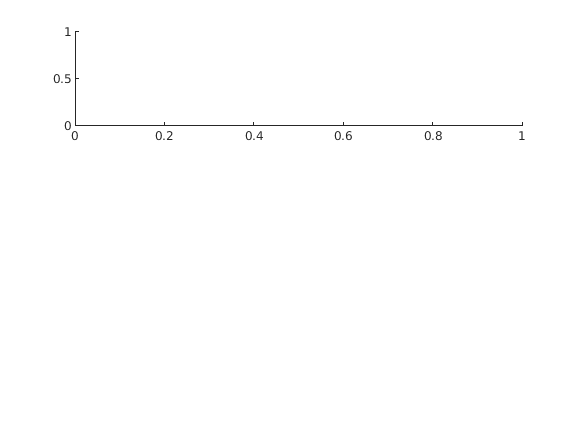

% Reference Noise Signal
figure;
subplot(3, 1, 1);

plot(t, noiseReference);

Error using plot
Vectors must be the same length.

xlabel('Time (t)');
ylabel('Amplitude');
title('Reference Noise Signal');
axis tight
subplot(3, 1, 2);
plot(t, numNoise);
xlabel('Time (t)');
ylabel('Amplitude');
title('Corrupted Noise Signal');
axis tight
subplot(3, 1, 3);
%plot(t, numFiltered);
xlabel('Time (t)');
ylabel('Amplitude');
title('Denoised Signal (For CrossChecking)');
axis tight

## RLS Implementation

M = 7;
lambda = 1;
lambdaInv = 1 / lambda;
delta = 5;
deltaInv = 1 / delta;

N = length(numNoise);
w = zeros(M, 1);
P = deltaInv * eye(M);
e = zeros(N, 1);

noiseReference = noiseReference(:);
numNoise = numNoise(:);
m = 0;

w1 = zeros(330744, 7);
for i = M:N
    y = noiseReference(i:-1:i-M+1);
    e(i) = numNoise(i) - (w' * y);
    k = (P * y)/(lambda + (y' * P * y));
    P = (P - (k * y' * P)) * lambdaInv;
    w = w + (k * e(i));
    m = m + 1;
    w1(m, :) = w(:, 1);
end
e = normalize(e, 'range', [-1 1]);

fprintf('Numbersof iterations performed: %d\n', m);

Numbersof iterations performed: 220649


## Plotting results

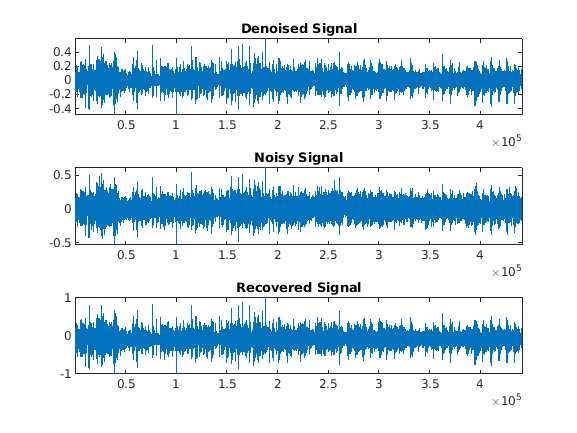

figure;
subplot(3, 1, 1);
plot(numFiltered);
title('Denoised Signal');
axis tight
subplot(3, 1, 2);
plot(numNoise);
title('Noisy Signal');
axis tight;
subplot(3, 1, 3);
plot(e);
title('Recovered Signal');
axis tight;

suptitle('ANC using RLS Algorithm');

Unrecognized function or variable 'suptitle'.

figure;
%plot(numFiltered, 'r');
hold on;
plot(e, '--g');
title('Comparision of Denoised Signal & Filter Output');
legend('Denoised Signal', 'RLS Output');

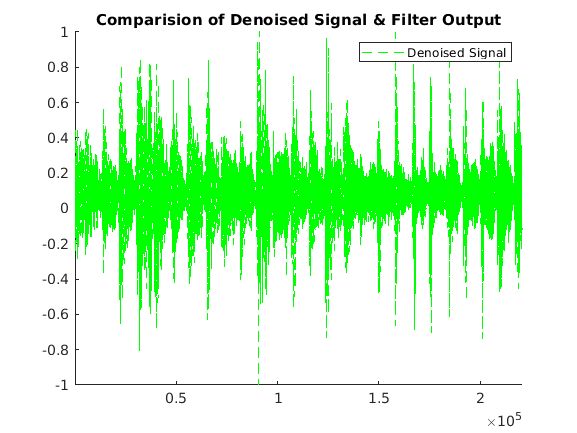

axis tight

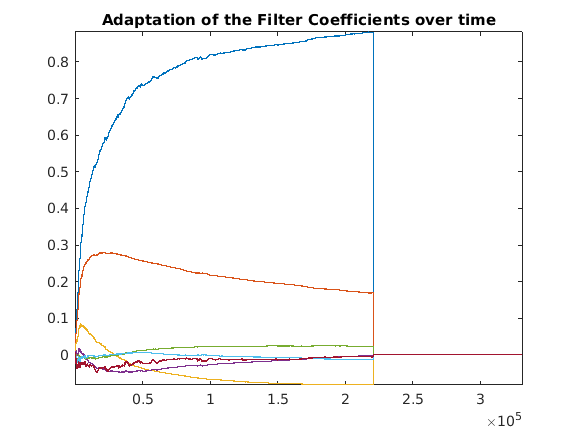

figure;
plot(w1);
title('Adaptation of the Filter Coefficients over time');
axis tight

## Listen to the Results !!!

%sound(numNoise, fs);
audiowrite('RLS_o1.wav',e, fs);